% double loop
clear all;

% PVPCS DC/DC
s = tf('s');
% syms s
fs = 20e+3; % 20kHz
L = 1.5e-3; % 1.5mH
RL = 0.3;   % 0.3ohm
C = 470e-6; % 470uF
RC = 0.09;  % 0.09ohm
Req = 20.8; % 20.8ohm
Vdc = 400;  % 400V

% Transfer Function
delta = L*C*(Req+RC)*s^2+(C*Req*RC+C*Req*RL+C*RC*RL+L)*s + Req+RL;

Gv= -Vdc*(C*Req*RC*s+Req)/delta

Gv =
 
          -0.3519 s - 8320
  ---------------------------------
  1.473e-05 s^2 + 0.005325 s + 21.1
 
연속시간 전달 함수입니다.
모델 속성


Gi= Vdc*(C*(Req+RC)*s+1)/delta

Gi =
 
            3.927 s + 400
  ---------------------------------
  1.473e-05 s^2 + 0.005325 s + 21.1
 
연속시간 전달 함수입니다.
모델 속성


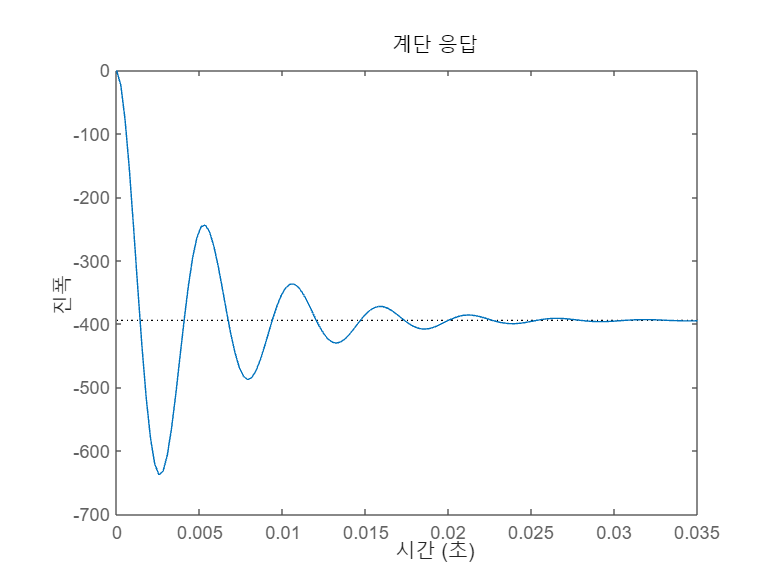

step(Gv)


% Voltage Controller
Kpv = Req*C;            % pole zero cancel
Kiv = 1;
Gcv = (Kpv*s+Kiv)/s;    % PI control

% Current Controller
Kpc = L;                % pole zero cancel 
Kic = RL; 
Gci = (Kpc*s+Kic)/s;    % PI control

% reference
Vpv_ref = 300; 
Ipv_ref = 10;


% % SISOTOOL
% T = sisoinit(1); 
% T.F.Value = Vpv_ref;
% T.G.Value = Gv;
% T.C.Value = Gcv;
% sisotool(T)